%clear crap
clear all

%importing data
data_1 = readtable("AIT/SAMPLE1_POL.csv");

data_2 = readtable("AIT/SAMPLE2_POL.csv");

data_3 = readtable("AIT/SAMPLE3_POL.csv");

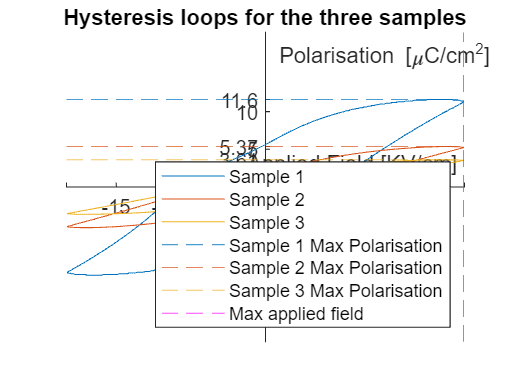


%subsetting strain field and polarisation data
field_1 = table2array(data_1(:,3));
pol_1 = table2array(data_1(:,4));
strain_1 = table2array(data_1(:,7));
max_pol_1 = max(pol_1); %extracting max polarisation
min_pol_1 = min(pol_1); %extracting min polarisation

field_2 = table2array(data_2(:,3));
pol_2 = table2array(data_2(:,4));
strain_2 = table2array(data_2(:,7));
max_pol_2 = max(pol_2); %extracting max polarisation
min_pol_2 = min(pol_2); %extracting min polarisation

field_3 = table2array(data_3(:,3));
pol_3 = table2array(data_3(:,4));
strain_3 = table2array(data_3(:,7));
max_pol_3 = max(pol_3); %extracting max polarisation
min_pol_3 = min(pol_3); %extracting min polarisation

%extracting maximum field
max_field_1 = max(field_1);
max_field_2 = max(field_2);
max_field_3 = max(field_3);
max_field = max([max_field_1;max_field_2;max_field_3]);

%plotting figure 1 (polarisation)
figure1 = plot(field_1,pol_1);
hold on %plotting on the same graph
figure1 = plot(field_2,pol_2);
figure1 = plot(field_3,pol_3);

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;
ylim([-20.5 20.5])
yticks([-10,-5,0,max_pol_3,5,max_pol_2,10,max_pol_1])
xticks([-20 -15 -10 -5 0 5 10 15 20])
%adding peak lines
yline(max_pol_1,"Color","#0072BD","LineStyle","--")
yline(max_pol_2,"Color","#D95319","LineStyle","--")
yline(max_pol_3,"Color","#EDB120","LineStyle","--")
xline(max_field,"m--")

% yline(min_pol_1,"Color","#0072BD","LineStyle","--")
% yline(min_pol_2,"Color","#D95319","LineStyle","--")
% yline(min_pol_3,"Color","#EDB120","LineStyle","--")

%labelling graph
xlabel("Applied Field [KV/cm]");
ylabel("Polarisation [{\mu}C/cm{^2}]");
title("Hysteresis loops for the three samples")
legend("Sample 1", ...
    "Sample 2", ...
    "Sample 3", ...
    "Sample 1 Max Polarisation", ...
    "Sample 2 Max Polarisation", ...
    "Sample 3 Max Polarisation", ...
    "Max applied field",...
    "Location","SouthEast" ...
    )

hold off %end plotting

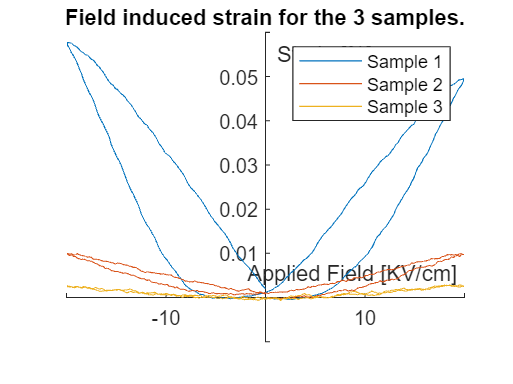


%plotting figure 2 (strain)
figure2 = plot(field_1,strain_1);
hold on %plotting on the same graph
figure2 = plot(field_2,strain_2);
figure2 = plot(field_3,strain_3);

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%labelling graph
xlabel("Applied Field [KV/cm]");
ylabel("Strain [%]");
title("Field induced strain for the 3 samples.")
legend("Sample 1","Sample 2","Sample 3")

hold off %end plotting